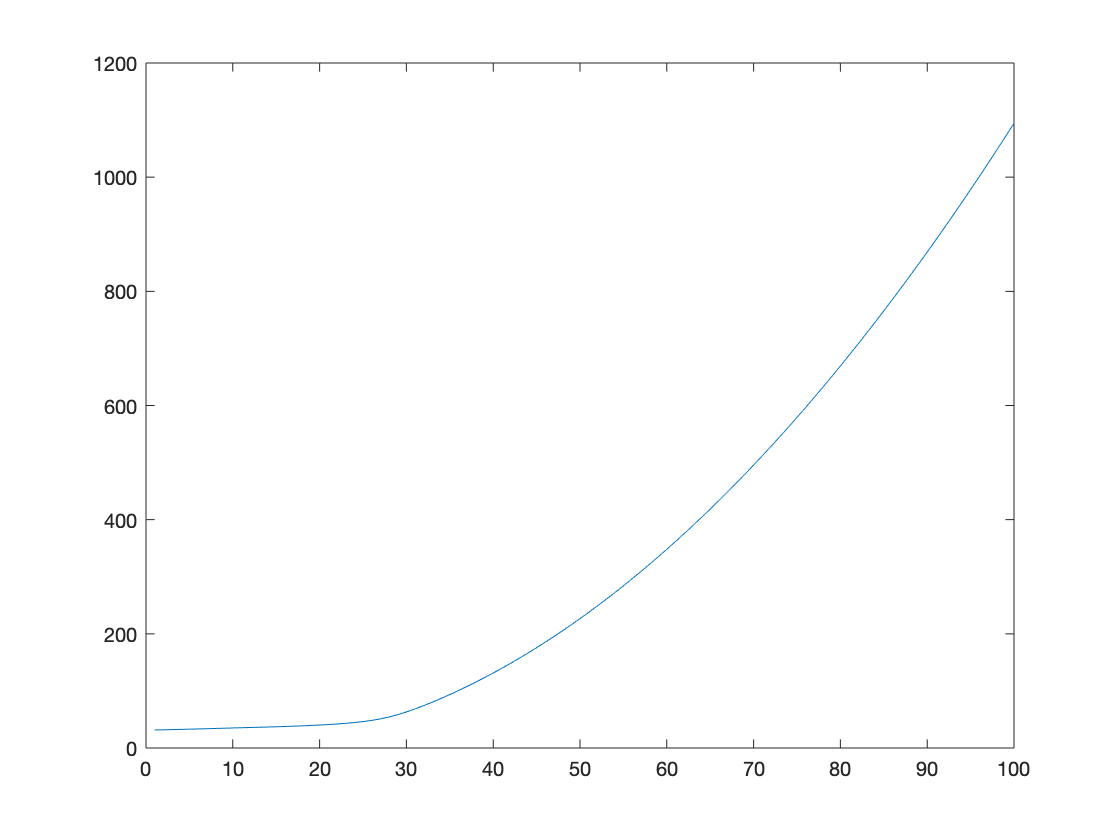

clear 
close all
M = [5 5 0 0 ; 
    5 5 0 0 ; 
    4 4 0 0 ; 
    0 0 4 4 ; 
    0 0 5 5 ];
omega = [1 2 4 5 6 8 9 10 11 13 14 15 16 17 19];
Omega = zeros(5, 4);
Omega(omega) = 1;
M_Omega = M.*Omega;
rak = 2;
maxiter = 100;
[X ,RMSE] = LP2(M,M_Omega,Omega,rak,maxiter);
plot(RMSE)

## test

M = randn(150, 10)* randn(10,200); array_Omega = binornd( 1, 0.3, [ 150, 200 ] ); M_Omega = M.*array_Omega;

[X ,RMSE] = LP2(M,M_Omega,array_Omega,10,50); plot(RMSE)